# 贝叶斯优化

[https://en.wikipedia.org/wiki/Bayesian_optimization](https://en.wikipedia.org/wiki/Bayesian_optimization)

[https://ww2.mathworks.cn/help/stats/bayesian-optimization-workflow.html](https://ww2.mathworks.cn/help/stats/bayesian-optimization-workflow.htmll)

[https://ww2.mathworks.cn/help/stats/bayesopt.html](https://ww2.mathworks.cn/help/stats/bayesopt.html)

## 基本介绍

**贝叶斯优化**是用于不具有任何功能形式的[黑盒](https://en.wikipedia.org/wiki/Black_box)函数[[1]](https://en.wikipedia.org/wiki/Bayesian_optimization#cite_note-1)进行[全局优化](https://en.wikipedia.org/wiki/Global_optimization)的[顺序设计](https://en.wikipedia.org/wiki/Sequential_analysis)策略。它通常用于优化昂贵的评估功能。

- Jonas Mockus (2012). [Bayesian approach to global optimization: theory and applications](https://books.google.com/books?id=VuKoCAAAQBAJ&printsec=frontcover#v=onepage&q=%22global%20optimization%22&f=false). 

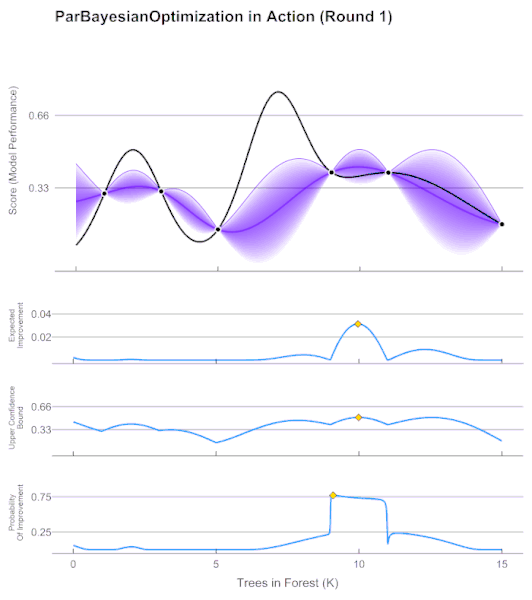

### 贝叶斯定理：				

贝叶斯优化之所以称作“贝叶斯”,是因为优化过程中利用了著名的“贝叶斯定理”(1763): 


$$P\left(B_{i} \mid A\right)=\frac{P\left(B_{i}\right) P\left(A \mid B_{i}\right)}{\sum_{j=1}^{n} P\left(B_{j}\right) P\left(A \mid B_{j}\right)}$$


### 贝叶斯优化：

#### 问题对象：

贝叶斯优化对于以下情况特别有利：难以评估 max(f(x)),x属于特定范围 ，f(x)是具有未知结构的黑匣子，依赖少于20个[维](https://en.wikipedia.org/wiki/Dimension)，并且不评估[导数](https://en.wikipedia.org/wiki/Derivative)。[[6]](https://en.wikipedia.org/wiki/Bayesian_optimization#cite_note-:0-6)

#### 优化策略：

因此贝叶斯策略是将其视为随机函数并将其放在[优先级](https://en.wikipedia.org/wiki/Prior_distribution)之上。先验捕获有关功能行为的信念。在收集了作为数据处理的功能评估之后，先验值被更新以形成目标函数的[后验分布](https://en.wikipedia.org/wiki/Posterior_distribution)。后验分布又用于构造确定下一个查询点的采集函数（通常也称为填充采样标准）。

#### 常用方法：

- [Kriging的](https://en.wikipedia.org/wiki/Kriging)方法中使用[高斯过程](https://en.wikipedia.org/wiki/Gaussian_process)

- 用Parzen-Tree估计器为“高”和“低”点构造两个分布，然后找到使预期改进最大化的位置。

## 算法介绍

#### **目标函数**

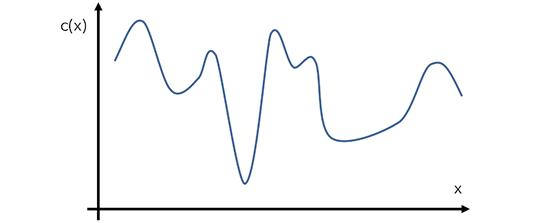

构造一个函数c(x)的假设例子，或者给定输入值x的模型的成本。当然，这个函数看起来是什么样子对优化器是隐藏的——这就是c(x)的真实形状，行话中被称为“**目标函数**”。

surrogate function

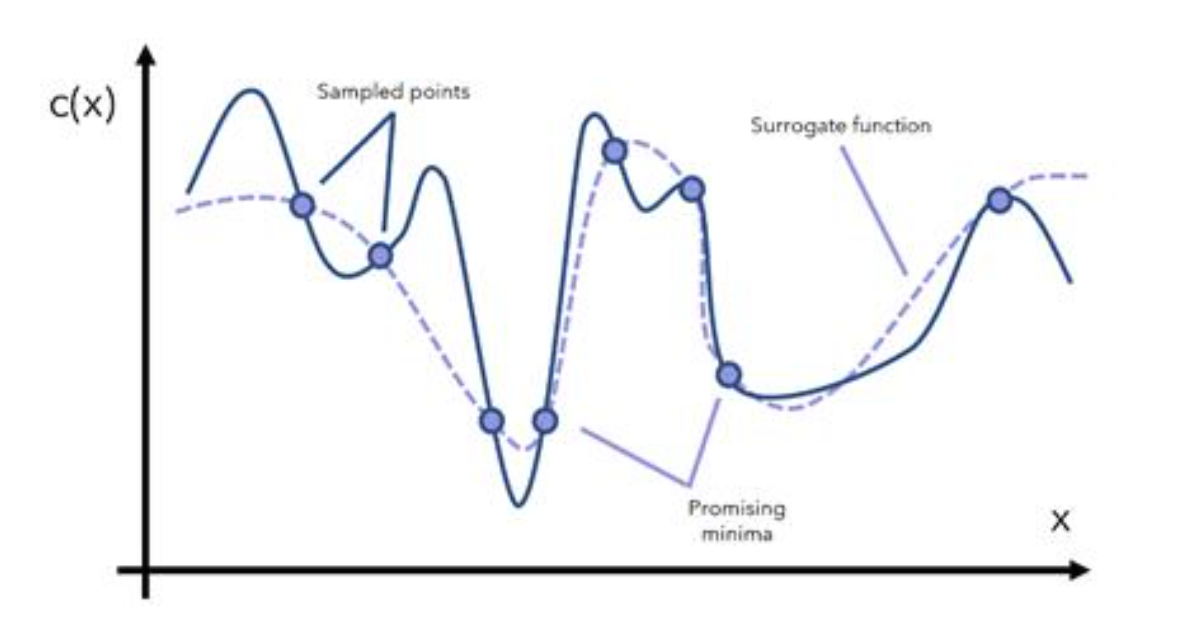

代理函数可以帮助确定哪些点是可能的最小值。我们决定从这些有希望的区域中抽取更多样本，并相应地更新代理函数。

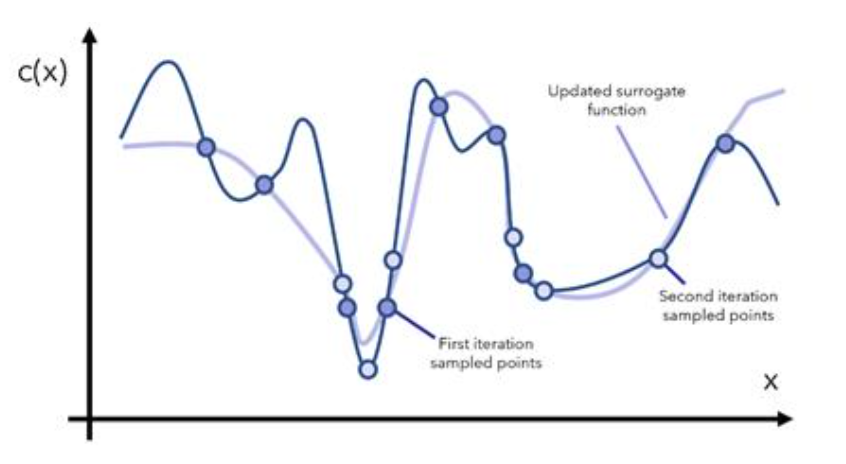

#### 采集函数

#### 算法流程

 初始化一个高斯过程的“代理函数”先验分布。

· 选择多个数据点x，使运行在当前先验分布上的采集函数a(x)最大化。

· 对目标成本函数c(x)中的数据点x进行评估，得到结果y。

· 用新的数据更新高斯过程的先验分布，产生后验（在下一步将成为先验）。

· 重复步骤2-5进行多次迭代。

· 解释当前的高斯过程分布（成本极低）来找到全局最小值。

### 常用模型

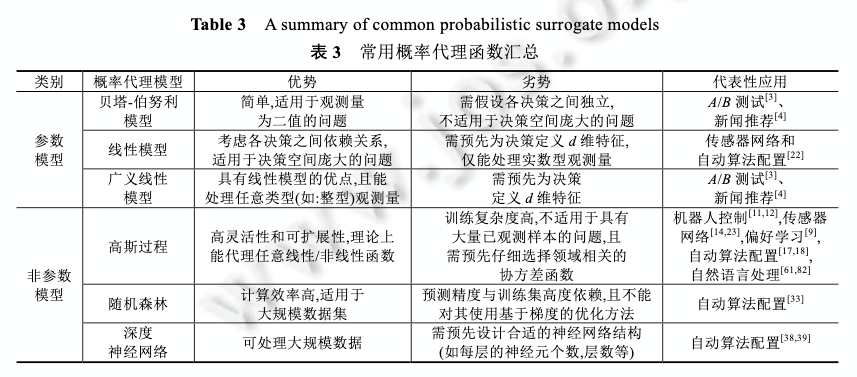

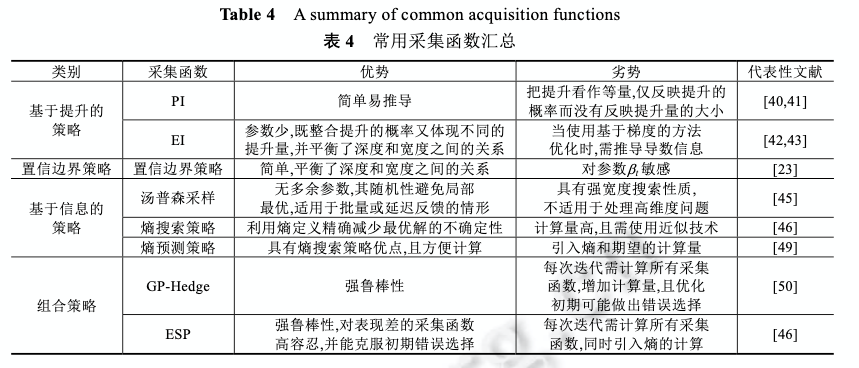

## 贝叶斯优化实战

### 例一：使用`bayesopt`以最小化交叉验证损失

This example shows how to create a `BayesianOptimization` object by using `bayesopt` to minimize cross-validation loss.

针对 `ionosphere `数据 优化KNN分类器的超参数，即找到使交叉验证损失最小的KNN超参数。有`bayesopt`最小化在随后的超参数：

- 最近邻居的大小从1到30

- 距离函数`'chebychev'`，`'euclidean'`和`'minkowski'`。

`ionosphere database 电离层数据集 `需要根据给定的电离层中的自由电子的雷达回波预测大气结构。

load ionosphere
rng default

？

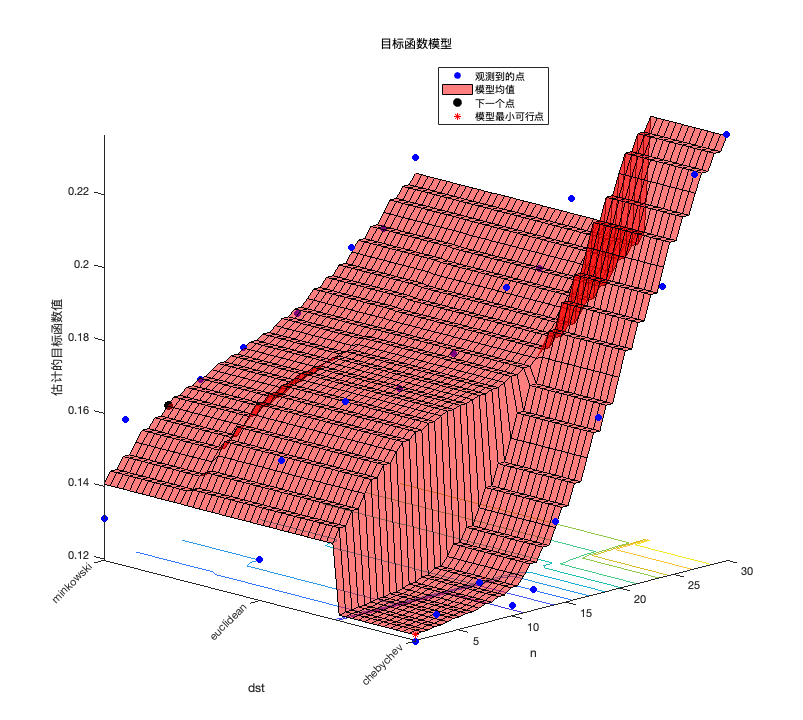

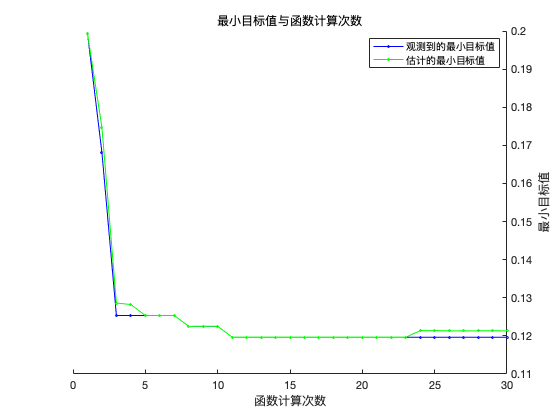

results =   BayesianOptimization - 属性:

                      ObjectiveFcn: @(x)kfoldLoss(fitcknn(X,Y,'CVPartition',c,'NumNeighbors',x.n,'Distance',char(x.dst),'NSMethod','exhaustive'))
              VariableDescriptions: [1×2 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 0.1197
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 0.1213
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 52.6524
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        Err

num = optimizableVariable('n',[1,30],'Type','integer');
dst = optimizableVariable('dst',{'chebychev','euclidean','minkowski'},'Type','categorical');
c = cvpartition(351,'Kfold',5);
fun = @(x)kfoldLoss(fitcknn(X,Y,'CVPartition',c,'NumNeighbors',x.n,...
    'Distance',char(x.dst),'NSMethod','exhaustive'));
results = bayesopt(fun,[num,dst],'Verbose',0,...
    'AcquisitionFunctionName','expected-improvement-plus')

### 例二：以文件为例进行贝叶斯优化

注意我们修改了 loss function 的结构 变成了. 模式

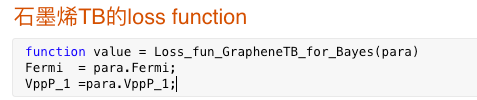

这里 我们要用到 [optimizableVariable](https://ww2.mathworks.cn/help/stats/optimizablevariable.html?searchHighlight=optimizableVariable&s_tid=srchtitle#d123e611210)

`variable = optimizableVariable(Name,Range)`

`variable = optimizableVariable(Name,Range,Name,Value)`

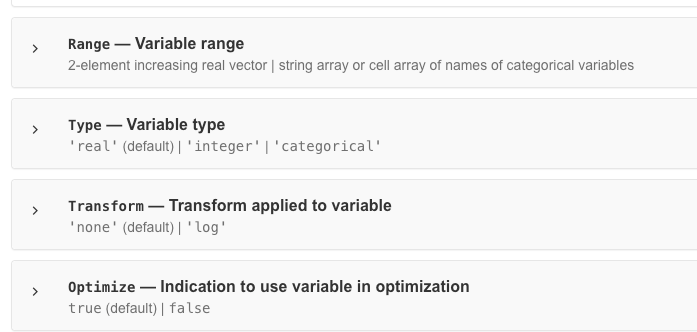

我们详细记录下 Bayesopt 所用到的 键值对

#### **Algorithm Control**

- `'AcquisitionFunctionName'`** — Function to choose next evaluation point**

-                                                             `'expected-improvement-per-second-plus'` (default) 

-                                                             `'expected-improvement'` 

-                                                             `'expected-improvement-plus'` 

-                                                              `'expected-improvement-per-second'` 

-                                                             `'lower-confidence-bound'` 

-                                                             `'probability-of-improvement'`

- `'ExplorationRatio'`** — Propensity to explore**

-                                                                 `0.5` (default) | positive real

-                                                               begin > 0.5 end <0.5 recom 0.5 always

- `'UseParallel'`** — Compute in parallel**

-                                                                 `false` (default) | `true`

**Starting and Stopping**

- `'MaxObjectiveEvaluations'`** — Objective function evaluation limit**

-                                                                 `30` (default) | positive integer

- `'MaxTime'`** — Time limit**

-                                                                  `Inf` (default) | positive real

- `'NumSeedPoints'`** — Number of initial evaluation points**

-                                                                 `4` (default) | positive integer

**Constraints**

#### **Reports, Plots, and Halting**

- `'Verbose'`** — Command-line display level**

-                                                                 `1` (default) | `0` | `2`

- `'OutputFcn'`** — Function called after each iteration**

-                                                                 like a event

- `'SaveFileName'` **—** **File name for the** `@saveToFile` **output function**

- `                              'BayesoptResults.mat'` (default) | character vector | string scalar

- `'SaveVariableName'`** — Variable name for the **`@assignInBase`** output function**

- `                              'BayesoptResults'` (default) | character vector | string scalar

- `'PlotFcn'`** — Plot function called after each iteration**

- `                              {@plotObjectiveModel,@plotMinObjective}` (default) | `'all'` | function handle | cell array of function handles

#### **Initialization**

- `'InitialX'`** — Initial evaluation points**

- **....... 不太需要**

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Fermi |       VppP_1 |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      4.8931 |      2.7963 |      4.8931 |      4.8931 |      0.29935 |       9.9651 |


|    2 | Best   |      4.6496 |     0.92142 |      4.6496 |      4.6681 |      -4.6728 |       1.6415 |


|    3 | Accept |      6.3904 |      1.0087 |      4.6496 |      4.6497 |      -5.3048 |      -9.3987 |


|    4 | Accept |      6.5793 |      0.9582 |      4.6496 |      4.6497 |       6.5561 |       -6.124 |


|    5 | Best   |      4.2648 |     0.81251 |      4.2648 |       4.265 |       -4.288 |       4.8369 |


|    6 | Accept |      5.4642 |     0.83431 |      4.2648 |      4.2652 |        5.441 |       6.0135 |


|    7 | Accept |      9.9603 |     0.86811 |      4.2648 |      4.2644 |      -9.9835 |       7.4121 |


|    8 | Best   |      2.4521 |      1.1651 |      2.4521 |       2.519 |      -2.4753 |       3.3563 |


|    9 | Accept |      5.2373 |     0.95063 |      2.4521 |       2.453 |      -2.1708 |      -9.9901 |


|   10 | Accept |      3.0927 |     0.95914 |      2.4521 |      2.4537 |      -2.0766 |       6.5217 |


|   11 | Best   |      1.8582 |      1.1822 |      1.8582 |      1.8592 |      -1.5057 |      0.95512 |


|   12 | Best   |      1.3326 |     0.82371 |      1.3326 |      1.3352 |     -0.19423 |      0.70334 |


|   13 | Best   |     0.62437 |     0.83575 |     0.62437 |     0.73459 |      0.43588 |       1.9921 |


|   14 | Accept |     0.81888 |     0.77237 |     0.62437 |     0.78406 |      0.79569 |       2.8181 |


|   15 | Accept |     0.91378 |      1.0258 |     0.62437 |     0.82112 |      0.88971 |       2.2152 |


|   16 | Best   |     0.40942 |     0.84974 |     0.40942 |     0.43488 |      0.37301 |        2.688 |


|   17 | Best   |     0.30124 |     0.83354 |     0.30124 |     0.29979 |     -0.23175 |       3.0351 |


|   18 | Best   |     0.18071 |     0.74038 |     0.18071 |     0.23782 |     -0.10958 |       2.7535 |


|   19 | Accept |     0.26598 |     0.72631 |     0.18071 |     0.24574 |     -0.21332 |       2.6733 |


|   20 | Accept |     0.19274 |     0.88474 |     0.18071 |     0.23193 |     -0.12287 |       2.7234 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Fermi |       VppP_1 |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.23387 |     0.82359 |     0.18071 |      0.2298 |     -0.17104 |       2.6737 |


|   22 | Accept |      10.253 |     0.81157 |     0.18071 |      0.2306 |       9.9802 |       9.9954 |


|   23 | Accept |     0.25731 |     0.73896 |     0.18071 |     0.23355 |     -0.20165 |       2.6708 |


|   24 | Accept |      9.9762 |     0.71928 |     0.18071 |     0.23411 |      -9.9994 |      -4.2533 |


|   25 | Accept |      10.019 |     0.81512 |     0.18071 |     0.23439 |       9.9954 |    0.0061171 |


|   26 | Accept |      10.254 |     0.72741 |     0.18071 |     0.23466 |       9.9817 |      -9.9955 |


|   27 | Accept |      5.4383 |     0.77476 |     0.18071 |     0.23521 |        2.839 |      -9.9994 |


|   28 | Accept |      10.299 |       1.051 |     0.18071 |     0.23508 |      -9.9814 |      -9.9917 |


|   29 | Accept |     0.20774 |     0.81523 |     0.18071 |     0.23062 |     -0.12897 |       2.8974 |


|   30 | Accept |      7.3878 |     0.88438 |     0.18071 |     0.23094 |      -6.3513 |       9.9972 |


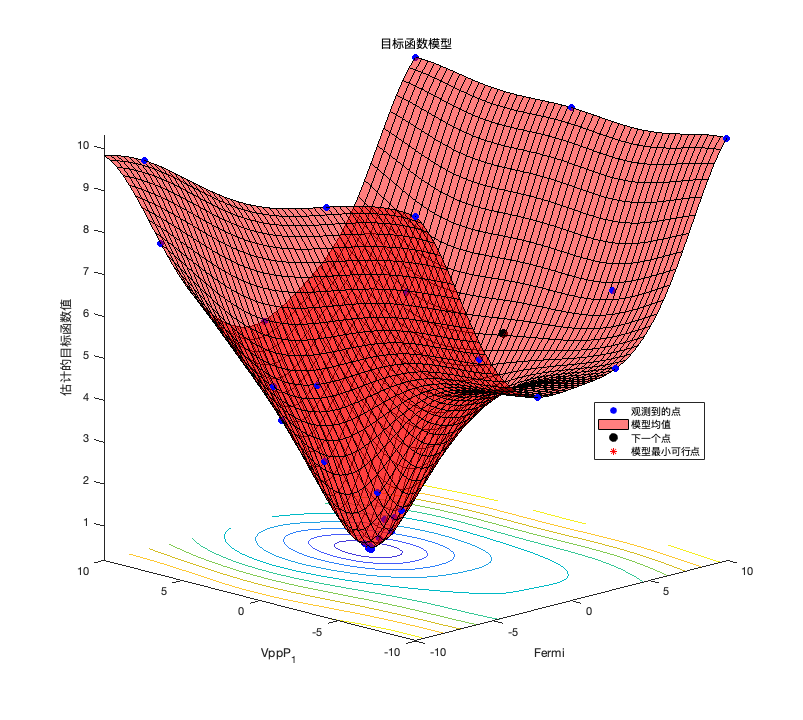

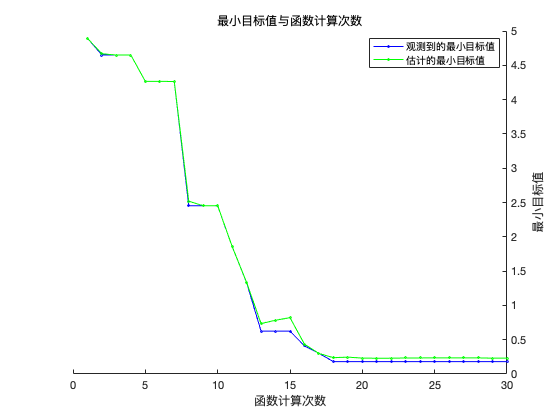


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 30。
函数计算总次数: 30
总历时: 64.9493 秒
总目标函数计算时间: 28.1102

观测到的最佳可行点:
     Fermi      VppP_1
    ________    ______

    -0.10958    2.7535

观测到的目标函数值 = 0.18071
估计的目标函数值 = 0.23094
函数计算时间 = 0.74038

估计的最佳可行点(根据模型):
     Fermi      VppP_1
    ________    ______

    -0.10958    2.7535

估计的目标函数值 = 0.23094
估计的函数计算时间 = 0.79424



results =   BayesianOptimization - 属性:

                      ObjectiveFcn: @Loss_fun_GrapheneTB_for_Bayes
              VariableDescriptions: [1×2 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 0.1807
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 0.2309
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 64.9493
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        ErrorTrace: [30×1 double]
                  FeasibilityTrace: [30×1 logical]
     

Fermi = optimizableVariable('Fermi',[-10,10]);
VppP_1 = optimizableVariable('VppP_1',[-10,10]);
results = bayesopt(@Loss_fun_GrapheneTB_for_Bayes,[Fermi ,VppP_1 ],'Verbose',1,...
    'AcquisitionFunctionName','expected-improvement-plus')